# Noise and SNR

MR data is complex with real and imaginary components. Noise is present in each of these channels. The noise is zero mean with standard deviation `sigma` in each of the real and imaginary channels. The relation to SNR and modulus data is demonstrated here.

First, let's look at a non-complex normal distribution:

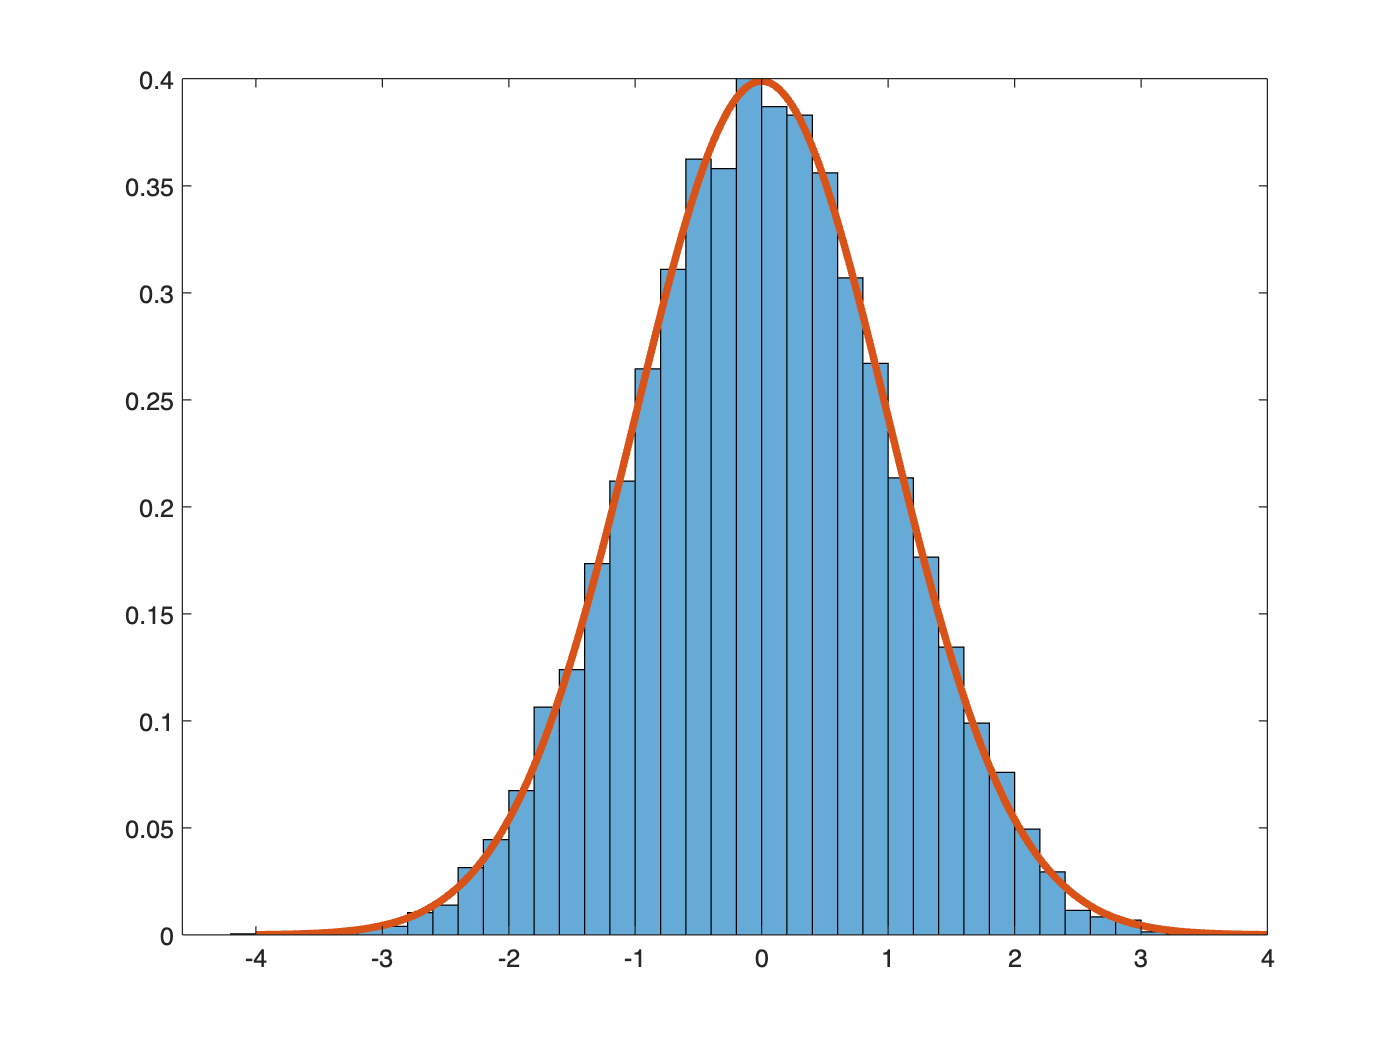

nSamples = 10000 ;

vrand = randn([nSamples 1],'like',1.0) ;

figure('Name','histogram')
histc = histogram(vrand);
histc.Normalization = "pdf"  ;

hold on
xval = linspace(-4,4,200) ;
mu = 0 ; sigma = sqrt(1) ;
yval = normpdf(xval, mu, sigma) ; % 1/sqrt(2.pi) exp(-1/2 * xval.^2) 

plot(xval,yval,'LineWidth',3)

Now a complex distribution. If we use `randn` with the `'like'` option (as below), it is equivalent to using variances of 1/2 (or standard deviations of `sqrt(1/2)` in the real and imaginary channels.

zrand = randn([nSamples 1],'like',1i) ; % Complex numbers

figure('Name','Complex Histogram')
histr = histogram(real(zrand)); % Histogram of real components
histr.Normalization = "pdf"  ;
hold on

var = 1/2; sigma = sqrt(var) ;
plot(xval, normpdf(xval,mu, sigma),'LineWidth',3) % Variances of R and I are 1/2

histi = histogram(imag(zrand));
histi.Normalization = "pdf"  ;

histmod = histogram(abs(zrand));
histmod.Normalization = "pdf"  ;
rpart = randn([nSamples 1]) * sigma ;
ipart = randn([nSamples 1]) * sigma ;

zsum = complex(rpart, ipart) ;

histsum = histogram(abs(zsum));
histsum.Normalization = "pdf"  ;



Defining SNR as `A/sigma` where `A` is the signal and `sigma` the std of each complex channel, the modulus distribution is given by a Rician distribution

### Regions where `A=0` ("air")

The Rician distribution simplifies to a Rayleigh distribution. The mean of the distribution (not the peak) is M=sigma sqrt(pi/2).

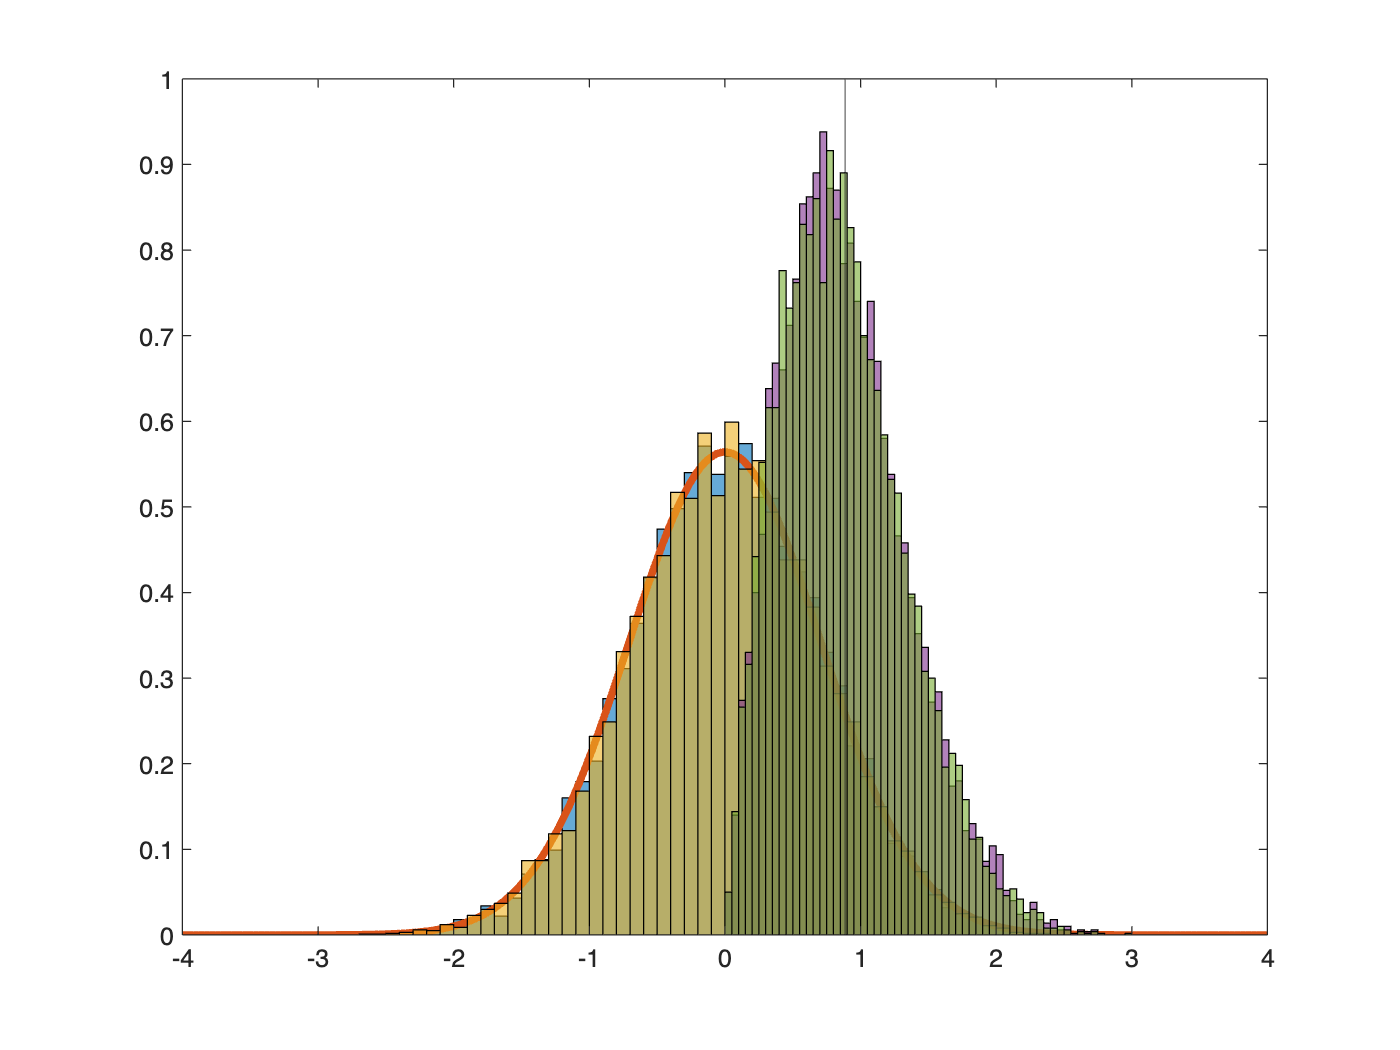

murice = sigma * sqrt(pi/2) ;
xline(murice)

The std is given by sqrt( (2 - pi/2) sigma^2 )

disp("mean expected: " + murice + ", std expected: " + sqrt( (2-pi/2)*sigma*sigma))

mean expected: 0.88623, std expected: 0.46325


pd = fitdist(abs(zsum), 'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0.878951   [0.870011, 0.887891]
    sigma =  0.45607   [0.449836, 0.46248]


### Regions where A/sigma >> 1(higher SNR)

The distribution becomes approximately Gaussian for most reasonable values of SNR in tissue. In this case, the mean is sqrt(A^2 + sigma^2) and the variance is sigma^2.

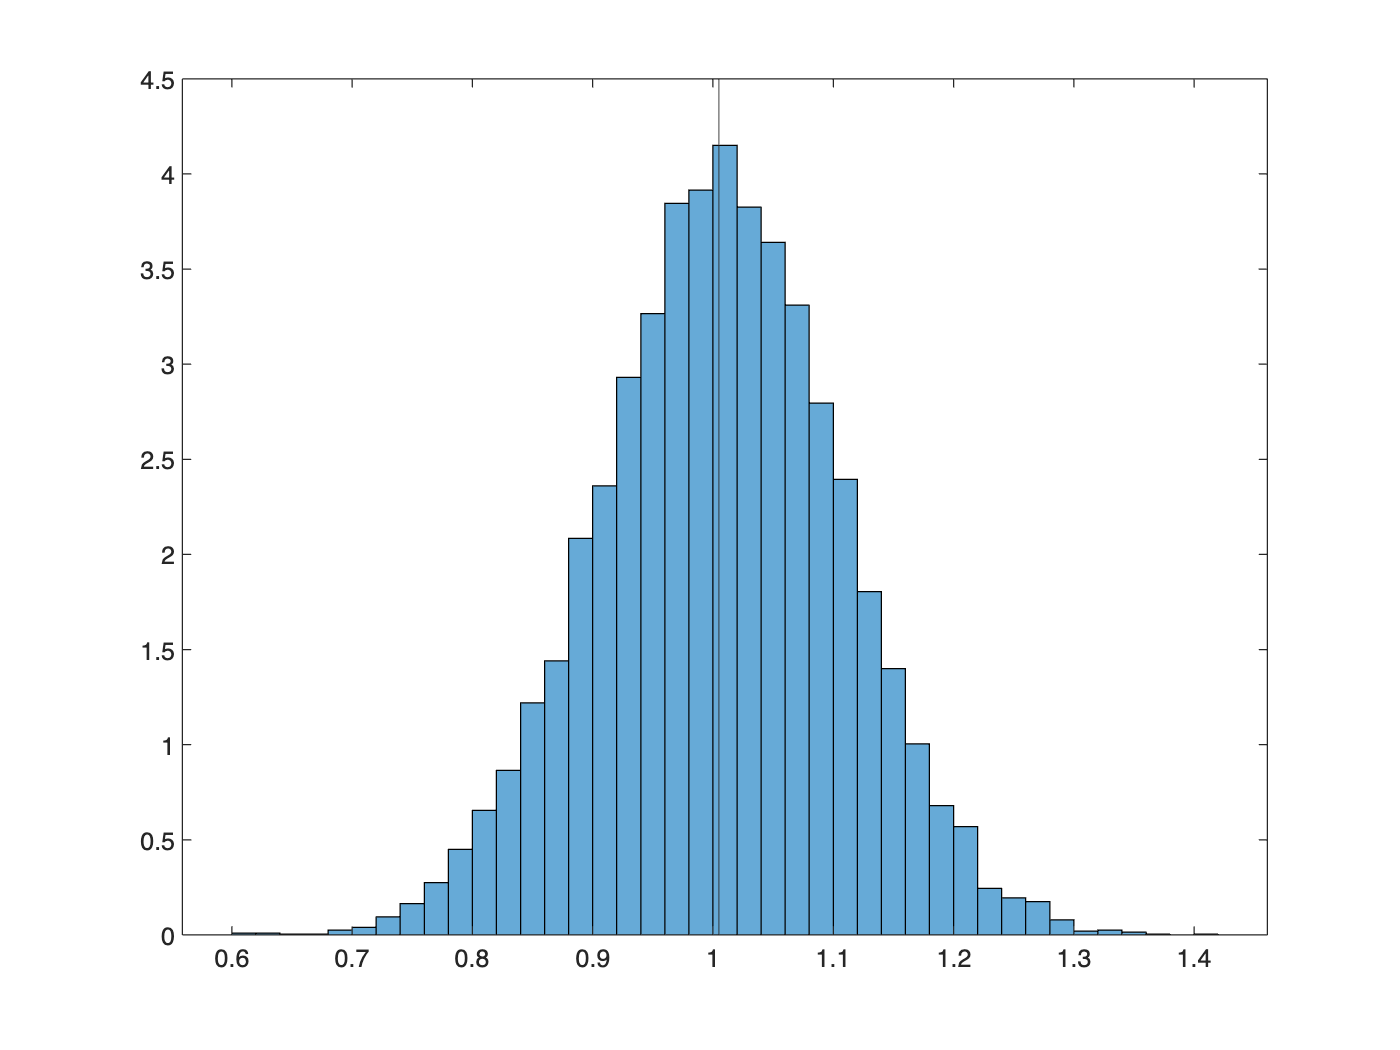

A = 1 ;
sigma = 1/10 ;

figure
rpart = randn([nSamples 1]) * sigma ;
ipart = randn([nSamples 1]) * sigma ;

zsum = complex(A + rpart, ipart) ;

histsum = histogram(abs(zsum));
histsum.Normalization = "pdf"  ;

meanHighSNR = sqrt(A.^2 + sigma.^2) ;
xline( meanHighSNR )

% Estimate the variance assuming this is a Gaussian.
disp("Expecting mean: " + meanHighSNR + ", variance: " + sigma^2 + ", sigma: " + sigma)

Expecting mean: 1.005, variance: 0.01, sigma: 0.1


pd = fitdist(abs(zsum), 'Normal')

pd =   NormalDistribution

  Normal distribution
       mu =  1.00569   [1.00373, 1.00766]
    sigma = 0.100303   [0.0989322, 0.101713]


### Verification in an Image

n = 64 ;
signal = 1 ;
sigma = 0.1 ;
nav = 6 ;

signalAndNoise = 0 ;
for iav =1:nav
    signalAndNoise = signalAndNoise + abs(repmat(signal,[n n]) + complex(sigma*randn(n,n), sigma*randn(n,n))) ;
end
signalAndNoise = signalAndNoise / nav ;

disp("Mean: "+ mean(signalAndNoise(:)) + ", std: " + std(signalAndNoise(:)) + ...
    ", mean/std: " + mean(signalAndNoise(:))/std(signalAndNoise(:)))

Mean: 1.0046, std: 0.040594, mean/std: 24.7471



disp("Single measure SNR: "+signal/sigma+", x sqrt(nav): " + signal/sigma*sqrt(nav))

Single measure SNR: 10, x sqrt(nav): 24.4949


### Summary

For an ROI in high SNR regions, the std of the ROI is the std of the underlying real and imaginary channels. At first sight, this seems lower than it should be (we are adding two lots of noise), but there is a cancellation effect due to the complex nature.

For an ROI in "air", the mean in an ROI is sigma * sqrt(pi/2). So, the corresponding sigma is the ROImean/1.25. Henkelmann points out that the ratio of the mean to the std in air should be 1.91 and this is a sanity check for offsets etc

### References

MATLAB doc for `randn`, `normpdf`

[https://doi.org/10.1002/mrm.1910340618](https://doi.org/10.1002/mrm.1910340618)